% =========================================================================
% EMPENNAGE PLANFORM, ELEVATOR, AND RUDDER SIZING SCRIPT
% =========================================================================
% Version 1: Ananjan Pillai
clear;     % Clears all variables from the MATLAB workspace to start fresh
clc;       % Clears the command window text output
close all; % Closes any open figure windows from previous runs

%% 1. INPUT VALUES (Updated Tailplane Dimensions & Sizing Parameters)
% Horizontal Stabilizer (H-Stab) Parameters[cite: 34, 35, 36, 37]
S_H            = 98.945930361135851; % Horizontal tail reference area (m^2)[cite: 34]
b_h            = 19.894313796774782; % Horizontal tail full span (m)[cite: 35]
AR_h           = (b_h^2) / S_H;        % Derived horizontal tail aspect ratio from updated S_H and b_h[cite: 34, 35, 36]
lambda_h       = 0.35;               % Assumed horizontal tail taper ratio (c_tip / c_root) - adjust as needed
Lambda_h_deg   = 37.3;               % H-stab quarter-chord sweep (deg) (wing 32.3 deg + 5 deg)[cite: 37]

% Vertical Stabilizer (V-Stab) Parameters[cite: 34, 35, 36, 37]
S_V            = 79.644934431064826; % Vertical tail reference area (m^2)[cite: 34]
b_v            = 11.288573651693278; % Vertical tail span / height (m)[cite: 35]
AR_v           = (b_v^2) / S_V;        % Derived vertical tail aspect ratio from updated S_V and b_v[cite: 34, 35, 36]
lambda_v       = 0.35;               % Assumed vertical tail taper ratio (c_tip / c_root) - adjust as needed
Lambda_v_deg   = 40.0;               % V-stab quarter-chord sweep (deg)[cite: 36, 37]

% Elevator Sizing Parameters (Typical ranges: span up to ~90%, chord 25-50% of tail chord)[cite: 13, 28]
elev_span_in_pct  = 10.0; % Inboard elevator start (% of h-stab semi-span, clear of fuselage/root)[cite: 13, 28]
elev_span_out_pct = 90.0; % Outboard elevator end (% of h-stab semi-span, avoiding tip vortex losses)[cite: 13, 28]
elev_chord_pct    = 30.0; % Elevator chord (% of local h-stab chord)[cite: 13, 28]

% Rudder Sizing Parameters (Typical ranges: span up to ~90%, chord ~25-35% / up to 50%)[cite: 13, 15, 29, 33]
rud_span_in_pct   = 10.0; % Bottom rudder start (% of v-stab span, clear of fuselage/root)[cite: 13, 29]
rud_span_out_pct  = 90.0; % Top rudder end (% of v-stab span, avoiding tip vortex/3D flow losses)[cite: 13, 29]
rud_chord_pct     = 32.0; % Rudder chord (% of local v-stab chord)[cite: 15, 29]

%% 2. DERIVE HORIZONTAL TAIL & ELEVATOR GEOMETRY (SEMI-SPAN)
b_h_half = b_h / 2; % Horizontal tail semi-span (m)

% Root and tip chords for trapezoidal horizontal tail: S_H = b_h * 0.5 * (c_root_h + c_tip_h)
c_root_h = S_H / (b_h_half * (1 + lambda_h)); % Root chord of horizontal tail (m)
c_tip_h  = c_root_h * lambda_h;               % Tip chord of horizontal tail (m)

% Leading-edge sweep from quarter-chord sweep and taper ratio
Lambda_h_c4_rad = deg2rad(Lambda_h_deg);
tan_le_h        = tan(Lambda_h_c4_rad) - 0.25 * (c_tip_h - c_root_h) / b_h_half;
sweep_le_h_rad  = atan(tan_le_h);

% Horizontal tail polygon corners (Root LE -> Tip LE -> Tip TE -> Root TE)
x_h_root_le = 0.0;
y_h_root_le = 0.0;
x_h_tip_le  = b_h_half * tan(sweep_le_h_rad);
y_h_tip_le  = b_h_half;
x_h_root_te = x_h_root_le + c_root_h;
y_h_root_te = 0.0;
x_h_tip_te  = x_h_tip_le + c_tip_h;
y_h_tip_te  = b_h_half;

x_h_tail = [x_h_root_le, x_h_tip_le, x_h_tip_te, x_h_root_te];
y_h_tail = [y_h_root_le, y_h_tip_le, y_h_tip_te, y_h_root_te];

% Elevator spanwise & chordwise coordinates
y_elev_in  = (elev_span_in_pct / 100) * b_h_half;
y_elev_out = (elev_span_out_pct / 100) * b_h_half;

c_elev_in  = c_root_h + (c_tip_h - c_root_h) * (y_elev_in / b_h_half);
c_elev_out = c_root_h + (c_tip_h - c_root_h) * (y_elev_out / b_h_half);

x_h_le_in  = y_elev_in * tan(sweep_le_h_rad);
x_h_le_out = y_elev_out * tan(sweep_le_h_rad);
x_h_te_in  = x_h_le_in + c_elev_in;
x_h_te_out = x_h_le_out + c_elev_out;

x_elev_le_in  = x_h_te_in - (elev_chord_pct / 100) * c_elev_in;
x_elev_le_out = x_h_te_out - (elev_chord_pct / 100) * c_elev_out;

x_elev = [x_h_te_in, x_h_te_out, x_elev_le_out, x_elev_le_in];
y_elev = [y_elev_in, y_elev_out, y_elev_out, y_elev_in];

%% 3. DERIVE VERTICAL TAIL & RUDDER GEOMETRY
% Root and tip chords for trapezoidal vertical tail: S_V = b_v * 0.5 * (c_root_v + c_tip_v)
c_root_v = S_V / (0.5 * b_v * (1 + lambda_v)); % Root chord of vertical tail (m)
c_tip_v  = c_root_v * lambda_v;               % Tip chord of vertical tail (m)

% Leading-edge sweep from quarter-chord sweep and taper ratio
Lambda_v_c4_rad = deg2rad(Lambda_v_deg);
tan_le_v        = tan(Lambda_v_c4_rad) - 0.25 * (c_tip_v - c_root_v) / b_v;
sweep_le_v_rad  = atan(tan_le_v);

% Vertical tail polygon corners (Root LE -> Tip LE -> Tip TE -> Root TE), Z along span/height
x_v_root_le = 0.0;
z_v_root_le = 0.0;
x_v_tip_le  = b_v * tan(sweep_le_v_rad);
z_v_tip_le  = b_v;
x_v_root_te = x_v_root_le + c_root_v;
z_v_root_te = 0.0;
x_v_tip_te  = x_v_tip_le + c_tip_v;
z_v_tip_te  = b_v;

x_v_tail = [x_v_root_le, x_v_tip_le, x_v_tip_te, x_v_root_te];
z_v_tail = [z_v_root_le, z_v_tip_le, z_v_tip_te, z_v_root_te];

% Rudder spanwise (Z) & chordwise (X) coordinates
z_rud_in  = (rud_span_in_pct / 100) * b_v;
z_rud_out = (rud_span_out_pct / 100) * b_v;

c_rud_in  = c_root_v + (c_tip_v - c_root_v) * (z_rud_in / b_v);
c_rud_out = c_root_v + (c_tip_v - c_root_v) * (z_rud_out / b_v);

x_v_le_in  = z_rud_in * tan(sweep_le_v_rad);
x_v_le_out = z_rud_out * tan(sweep_le_v_rad);
x_v_te_in  = x_v_le_in + c_rud_in;
x_v_te_out = x_v_le_out + c_rud_out;

x_rud_le_in  = x_v_te_in - (rud_chord_pct / 100) * c_rud_in;
x_rud_le_out = x_v_te_out - (rud_chord_pct / 100) * c_rud_out;

x_rud = [x_v_te_in, x_v_te_out, x_rud_le_out, x_rud_le_in];
z_rud = [z_rud_in, z_rud_out, z_rud_out, z_rud_in];

%% 4. CALCULATE ELEVATOR & RUDDER AREAS AND AREA RATIOS
% Total elevator area (both left and right sides)
area_elev_half   = polyarea(x_elev, y_elev);
area_elev_total  = 2 * area_elev_half;
Se_over_Sh       = area_elev_total / S_H;      % Dimensionless ratio Se / Sh
elev_area_pct_SH = Se_over_Sh * 100;           % Percentage of S_H

% Total rudder area
area_rud_total   = polyarea(x_rud, z_rud);
Sr_over_SV       = area_rud_total / S_V;       % Dimensionless ratio Sr / Sv
rud_area_pct_SV  = Sr_over_SV * 100;           % Percentage of S_V

% Display summary in command window
fprintf('\n=============================================================\n');

fprintf('          EMPENNAGE & CONTROL SURFACE SIZING SUMMARY          \n');

          EMPENNAGE & CONTROL SURFACE SIZING SUMMARY          


fprintf('=============================================================\n');

fprintf('H-Stab Area (S_H):       %.4f m^2 | Span (b_h): %.4f m | AR_h: %.2f\n', S_H, b_h, AR_h);

H-Stab Area (S_H):       98.9459 m^2 | Span (b_h): 19.8943 m | AR_h: 4.00


fprintf('H-Stab Root / Tip Chord: %.2f m / %.2f m\n', c_root_h, c_tip_h);

H-Stab Root / Tip Chord: 7.37 m / 2.58 m


fprintf('Total Elevator Area:     %.2f m^2  (%.2f%% of S_H | Se/Sh = %.4f)\n', area_elev_total, elev_area_pct_SH, Se_over_Sh);

Total Elevator Area:     23.75 m^2  (24.00% of S_H | Se/Sh = 0.2400)


fprintf('-------------------------------------------------------------\n');

-------------------------------------------------------------


fprintf('V-Stab Area (S_V):       %.4f m^2 | Span (b_v): %.4f m | AR_v: %.2f\n', S_V, b_v, AR_v);

V-Stab Area (S_V):       79.6449 m^2 | Span (b_v): 11.2886 m | AR_v: 1.60


fprintf('V-Stab Root / Tip Chord: %.2f m / %.2f m\n', c_root_v, c_tip_v);

V-Stab Root / Tip Chord: 10.45 m / 3.66 m


fprintf('Total Rudder Area:       %.2f m^2  (%.2f%% of S_V | Sr/Sv = %.4f)\n', area_rud_total, rud_area_pct_SV, Sr_over_SV);

Total Rudder Area:       20.39 m^2  (25.60% of S_V | Sr/Sv = 0.2560)


fprintf('=============================================================\n');

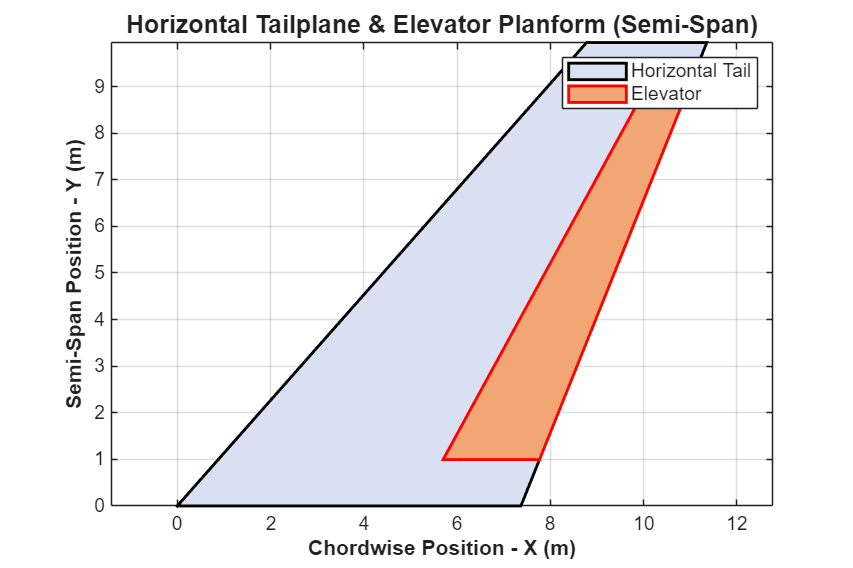


%% 5. PLOT HORIZONTAL TAIL & ELEVATOR PLANFORM (SEMI-SPAN)
figure('Color', 'white', 'Position', [100, 100, 750, 500]);
hold on;
patch(x_h_tail, y_h_tail, [0.85 0.88 0.95], 'EdgeColor', 'k', 'LineWidth', 1.5);
patch(x_elev, y_elev, [0.95 0.65 0.45], 'EdgeColor', 'r', 'LineWidth', 1.5);
xlabel('Chordwise Position - X (m)', 'FontSize', 11, 'FontWeight', 'bold');
ylabel('Semi-Span Position - Y (m)', 'FontSize', 11, 'FontWeight', 'bold');
title('Horizontal Tailplane & Elevator Planform (Semi-Span)', 'FontSize', 13, 'FontWeight', 'bold');
legend({'Horizontal Tail', 'Elevator'}, 'Location', 'northeast', 'FontSize', 10);
grid on;
axis equal;
box on;
hold off;

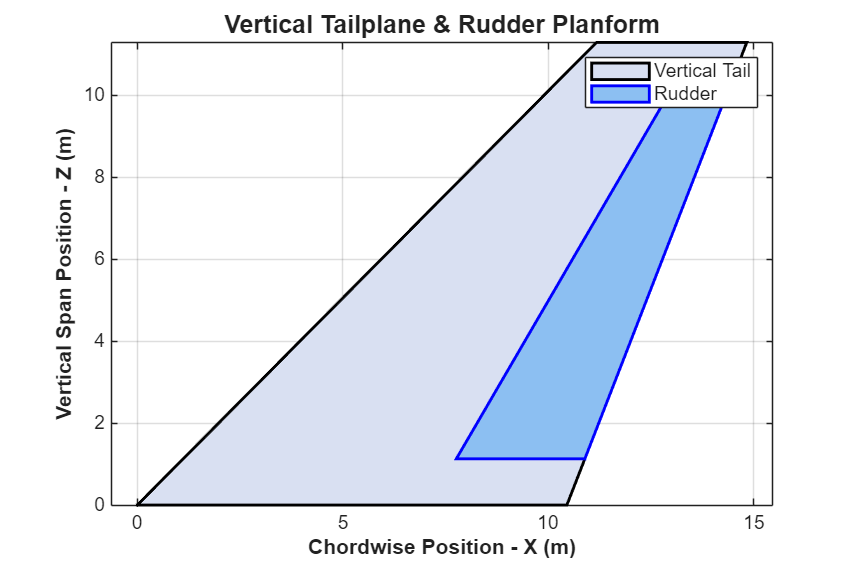


%% 6. PLOT VERTICAL TAIL & RUDDER PLANFORM
figure('Color', 'white', 'Position', [880, 100, 750, 500]);
hold on;
patch(x_v_tail, z_v_tail, [0.85 0.88 0.95], 'EdgeColor', 'k', 'LineWidth', 1.5);
patch(x_rud, z_rud, [0.55 0.75 0.95], 'EdgeColor', 'b', 'LineWidth', 1.5);
xlabel('Chordwise Position - X (m)', 'FontSize', 11, 'FontWeight', 'bold');
ylabel('Vertical Span Position - Z (m)', 'FontSize', 11, 'FontWeight', 'bold');
title('Vertical Tailplane & Rudder Planform', 'FontSize', 13, 'FontWeight', 'bold');
legend({'Vertical Tail', 'Rudder'}, 'Location', 'northeast', 'FontSize', 10);
grid on;
axis equal;
box on;
hold off;